The first part is raw data collection. By specifying use_real_data=true, the data will be collected from Yahoo finance. Otherwise, we will use the data from Das. paper.

use_real_data = false;

pause(2)
if use_real_data
initDate = '2017-01-01';
endDate = '2018-01-01'; 
initDate = datetime(initDate, 'InputFormat','yyyy-MM-dd');
endDate = datetime(endDate, 'InputFormat','yyyy-MM-dd');
% portfolio = ["URTH"; "HYG";"LQD"; "DBC";"CMR.TO"];
portfolio = ["URTH"; "HYG";"LQD";"DBC"];
c = containers.Map;
for k=1:length(portfolio)
   symbol = portfolio(k);
   data = Yahooscraper(convertStringsToChars(symbol), initDate, endDate, '1d');
   TT = table2timetable(data(:,[1,4]));
   TT.Properties.VariableNames = {convertStringsToChars(symbol)};
   c(symbol) = TT;
end
f = @(i) c(portfolio(i));
T = synchronize(f(1),f(2),f(3), f(4), 'Intersection');
prices = [T.URTH, T.HYG, T.LQD, T.DBC];
ts = timeseries(prices, datestr(T.Date));
ts.Name = " Portfolio Prices over Time";
plot(ts);
legend({'URTH'; 'HYG';'LQD';'DBC'});

% expected return
simple_returns = (prices(2:end,:)-prices(1:end-1,:))./prices(1:end-1,:);
%expected_returns = sum(simple_returns, 1)
expected_returns = sum(simple_returns) /size(simple_returns, 1);
% sample_covariance
sample_covariance = cov(simple_returns);
% exponentially- weighted average (EWA) returns
s = 2;

I = (size(prices, 1)-1):-1:1;
k = (1-2/(s+1)).^I;
exponentially_weighted_average_returns = k * simple_returns / sum(k)

annualized = 252;
avg_arr = expected_returns * annualized
cov_mat = sample_covariance * annualized
else
    cov_mat = [0.0017, -0.0017, -0.0021; -0.0017, 0.0396, 0.0309; -0.0021, 0.0309, 0.0392];
    avg_arr = [0.0493; 0.0770; 0.0886];
end

The second part is setting parameters for reinforcement learning environment.

%parameters
m = 15;
mus = reshape(linspace(.0526, .0886, m), [], 1);
T = 11;
cash = zeros(T, 1);
rho = 1;
G = 200;
w0 = 100;

tic
p = Portfolio("AssetCovar",cov_mat,"AssetMean",avg_arr);
p = setBounds(p,0);
p = setBudget(p,1,1);
pwgt= estimateFrontier(p, m)

pwgt =     0.9115    0.8516    0.7868    0.7213    0.6557    0.5901    0.5246    0.4590    0.3934    0.3278    0.2623    0.1967    0.1311    0.0656         0
    0.0217    0.0026         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0667    0.1458    0.2132    0.2787    0.3443    0.4099    0.4754    0.5410    0.6066    0.6722    0.7377    0.8033    0.8689    0.9344    1.0000


[prsk,pret] = estimatePortMoments(p, pwgt)

prsk =     0.0370
    0.0395
    0.0461
    0.0555
    0.0666
    0.0785
    0.0910
    0.1039
    0.1170
    0.1303


pret =     0.0525
    0.0551
    0.0577
    0.0603
    0.0628
    0.0654
    0.0680
    0.0706
    0.0731
    0.0757


ef = [pret(:), prsk(:)];
[grid, w0_idx] = gen_grid(w0, cash, ef, rho, {-3, 3}, 1);

Grid size: 119


toc

历时 0.521583 秒。


This is DP part. where we are interested in the optimal result. And this is going to be the benchmark of RL algorithms. 

tic
[grid, w0_idx] = gen_grid(w0, cash, ef, rho, {-3, 3}, 1);

Grid size: 119


tp_tables = get_trans_prob_tables(ef, grid, T, cash);
[best_ms, v_tables] = V(ef, grid, tp_tables, G, T);
p_table = calc_wealth_prob(grid, w0_idx, best_ms, tp_tables, T);
[p_len, p_width] = size(p_table);
G_idx = sum(grid < G) + 1;
prob = sum([p_table{p_len, G_idx:p_width}]);
prob 

prob = 0.6745

toc

历时 9.946841 秒。


We specify environment here.

env_type = 'line'

env_type = 'line'

avg_mu = 0.0718

line =   100.0000  107.1842  114.8698  123.1034  131.9316  141.4011  151.5585  162.4505  174.1236  186.6246  200.0000


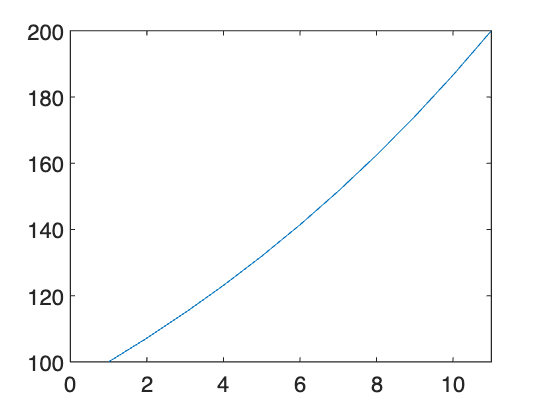

simulate_n_periods = 1;
simulate_dt = 1;
simulate_n_trials = 1;

if strcmp(env_type, 'line')

avg_mu = (G/w0) .^ (1/(T-1)) - 1
% insert_mu = find(ef(:, 1) >= avg_mu, 1, 'first');
insert_mu1 = avg_mu;
insert_t1 = 3;
insert_w1 = w0 .* (1 + insert_mu1) .^ (insert_t1-1);
insert_mu2 = avg_mu;
insert_t2 = 8;
insert_w2 = w0 .* (1 + insert_mu2) .^ (insert_t2-1);
line = spline([1 insert_t1 insert_t2 T], [w0 insert_w1 insert_w2 G], 1:T)
plot(line)
env = LineGoalGBWMEnvironment(G, T, grid, cash, w0_idx, pwgt, pret, prsk, line, simulate_n_periods, simulate_dt, simulate_n_trials);

elseif strcmp(env_type, 'scale')
    gamma = 1.2;
    env = ScaleGBWMEnvironment(G, T, grid, cash, w0_idx, pwgt, pret, prsk, gamma, simulate_n_periods, simulate_dt, simulate_n_trials);
elseif strcmp(env_type, 'sparse')
    env = SparseGoalGBWMEnvironment(G, T, grid, cash, w0_idx, pwgt, pret, prsk, simulate_n_periods, simulate_dt, simulate_n_trials);
elseif strcmp(env_type, 'factors')    
    env = SparseDiscreteGBWMEnvironment(G, T, grid, w0_idx, pwgt, pret, prsk, simulate_n_periods, simulate_dt, simulate_n_trials);
elseif strcmp(env_type, 'discrete')
    env = SparseDiscreteGBWMEnvironment(G, T, grid, w0_idx, pwgt, pret, prsk, simulate_n_periods, simulate_dt, simulate_n_trials);
end

test_env = SparseGoalGBWMEnvironment(G, T, grid, cash, w0_idx, pwgt, pret, prsk, simulate_n_periods, simulate_dt, simulate_n_trials);
validateEnvironment(env);

obs_info = getObservationInfo(env);
obs_info

obs_info =   rlNumericSpec - 属性:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "GBWM States"
    Description: "wealth, time, goal"
      Dimension: [3 1]
       DataType: "double"


act_info = getActionInfo(env);
rng(0);


We specify RL agent here.

agent_type = 'DQN'

agent_type = 'DQN'

if strcmp(agent_type, 'DQN')
init_opt = rlAgentInitializationOptions(NumHiddenUnit=16, UseRNN=false);
% DQN
agent = rlDQNAgent(obs_info, act_info, init_opt);
elseif strcmp(agent_type, 'G')
    agent = CustomGAgent(length(grid) * T, length(ef), 0.001, 0.1, obs_info, act_info, T, 0.95);
elseif strcmp(agent_type, 'Q')    
    q_table = rlTable(obs_info, act_info);
    critic = rlQValueFunction(q_table, obs_info, act_info);
    agent = rlQAgent(critic);
    optimizer_opt = rlOptimizerOptions("LearnRate", 1e-3, "GradientThreshold", 1);
    explore_opt = rl.option.EpsilonGreedyExploration;
    explore_opt.Epsilon = 1;
    q_opt = rlQAgentOptions("EpsilonGreedyExploration", explore_opt, "CriticOptimizerOptions", optimizer_opt);
    agent.AgentOptions = q_opt;
end
    
%getAction(agent, {rand(obs_info.Dimension)})


This part is model training.

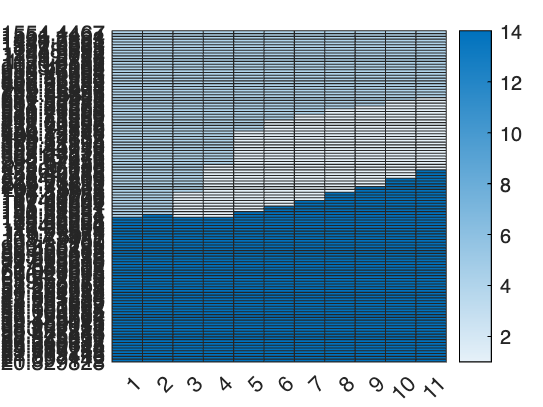

rl_probability = 0.5610

历时 50.674718 秒。


train_opt = rlTrainingOptions("MaxEpisodes", 100, "MaxStepsPerEpisode", 20, "ScoreAveragingWindowLength", 200, "Verbose", false, "Plots", "training-progress", "StopTrainingCriteria", "AverageReward", "StopTrainingValue", 100);
do_train = true;
if do_train
    train_stats = train(agent, env, train_opt);
end    

if strcmp(env_type, 'discrete')
        %testing part
    tic
    NumSimulations = 100;
    a=0;
    sim_opt = rlSimulationOptions("MaxSteps", 15,"NumSimulations", NumSimulations);
    experience = sim(env, agent, sim_opt);
    reward = {experience.Reward};
    for i = 1:NumSimulations
        a = a+reward{i}.Data(T-1);
    end
    rl_probability = a/NumSimulations
    toc
    %obtaining action grid for agents
    action_grid = zeros(length(grid), T);
    for g = 1:length(grid)
        for t = 1:T
            tmp_a = agent.getAction([g, t]);
            action_grid(g, t) = tmp_a{:};
        end
    end 
    
    heatmap(1:T, flip(grid), flip(action_grid))
else 
    % numeric
    action_grid = zeros(length(grid), T);
    policy = agent;
    for g = 1:length(grid)
        for t = 1:T 
            log_w = (log(grid(g)) - log(grid(1))) / (log(grid(end)) - log(grid(1)));
            t_norm = t / T;
            log_g = (log(G) - log(grid(1))) / (log(grid(end)) - log(grid(1)));
            tmp_a = getAction(policy, {[log_w, t_norm, log_g].'});
            action_grid(g, t) = tmp_a{:};
        end
    end
    heatmap(1:T, flip(grid), flip(action_grid))
    tic
    NumSimulations = 1000;
    a=0;
    sim_opt = rlSimulationOptions("MaxSteps", 15, "NumSimulations", NumSimulations);
    experience = sim(test_env, agent, sim_opt);
    reward = {experience.Reward};
    for i = 1:NumSimulations
        a = a+reward{i}.Data(T-1);
    end
    
    rl_probability = a/NumSimulations
    toc
end    

function [grid, w0_idx] = gen_grid(w0, cash, efficient_frontier, rho, Z_range, h)
    [z_min, z_max] = Z_range{:};
    t = size(cash, 1);
    
    mu_tmp = efficient_frontier(:, 1);
    sig_tmp = efficient_frontier(:, 2);
    mu_min = min(mu_tmp);
    mu_max = max(mu_tmp);
    sig_max = max(sig_tmp);
    sig_min = min(sig_tmp);
    
    emap_max = containers.Map('KeyType', 'int32', 'ValueType', 'double');
    emap_min = containers.Map('KeyType', 'int32', 'ValueType', 'double');

    for i = 1:t
        emap_max(i) = exp((mu_max - sig_max .^ 2 ./ 2) .* h .* i + z_max .* sig_max .* (h .* sqrt(i)));
        emap_min(i) = exp((mu_min - sig_max .^ 2 ./ 2) .* h .* i + z_min .* sig_max .* (h .* sqrt(i)));
    end
    
    w_min = Inf;
    w_max = -Inf;
    for i = 1:t
        cur_min = ( ...
            w0 .* emap_min(i) + ...
            sum(arrayfun(@(j) cash(j) .* emap_min(i - j + 1), 1:i)) ...
            );
        cur_max = ( ...
            w0 .* emap_max(i) + ...
            sum(arrayfun(@(j) cash(j) .* emap_max(i - j + 1), 1:i)) ...
            );
        w_min = min(cur_min, w_min);
        w_max = max(cur_max, w_max);
    end

    grid = [];
    cur = log(w_min);
    log_max = log(w_max);
    while cur < log_max
        grid = [grid; cur];
        cur = cur + sqrt(h) .* sig_min ./ rho;
    end
    grid = [grid; log_max];

    log_w0 = log(w0);
    shift = Inf;
    w0_idx = 1;
    for i = 1:size(grid, 1)
        x = grid(i);
        if x - log_w0 >= shift && x - log_w0 >= 0
            continue
        else
            shift = x - log_w0;
            w0_idx = i;
        end
    end
    grid = grid - shift;
    grid = exp(grid);
    disp(['Grid size: ' num2str(size(grid, 1))]);
end

function transfer_prob_ = cal_transfer_prob(t, i, j, ef_pair, grid, cash, h)
    stn_pdf = @(x) exp(-x .^ 2 ./ 2) ./ sqrt(2 .* pi);

    mu = ef_pair(1);
    sig = ef_pair(2);

    transfer_prob_fn = @(j) stn_pdf(1 ./ sig .* (log(grid(j) ./ (grid(i) + cash(t) )) - (mu - sig .^ 2 ./ 2) ));
    transfer_prob_ = transfer_prob_fn(j);
end 

function tp_tables = get_trans_prob_tables(ef, grid, T, cash)
    tp_tables = cell(size(ef, 1), 1);
    for ei = 1:size(ef, 1)
        ef_pair = ef(ei, :);
        tp_table = cell(T - 1, 1);
        for t = 1:T - 1
            row_t = cell(1, size(grid, 1));
            for i = 1:size(grid, 1)
                fn = @(j) cal_transfer_prob(t, i, j, ef_pair, grid, cash);
                trans_p = arrayfun(fn, 1:size(grid, 1));
                trans_p = trans_p ./ sum(trans_p);
                row_t{i} = trans_p;
            end
            tp_table{t} = row_t;
        end
        tp_tables{ei} = tp_table;
    end 
end

function v_dp = get_Vtable(grid, tp_table, G, T)
    v_dp = zeros(T, size(grid, 1));
    fullfill_idx = grid >= G;
    v_dp(T, fullfill_idx) = 1;
    v_dp(T, ~fullfill_idx) = 0;

    for t = T - 1:-1:1
        for i = 1:size(grid, 1)
            trans_p = tp_table{t}{i};
            v_dp(t, i) = sum(v_dp(t + 1, :) .* trans_p);
        end 
    end
end    

function [best_ms, v_tables] = V(ef, grid, tp_tables, G, T)
    v_tables = cell(size(ef, 1), 1);
    for ei = 1: size(ef, 1)
        v_table = get_Vtable(grid, tp_tables{ei}, G, T);
        v_tables{ei} = v_table;
    end 
    
    best_ms = cell(T, size(grid, 1)); 
    for t = 1: T
        for i = 1: size(grid, 1)
            best_ef_idx = 0;
            cur_best = -Inf;
            for j = 1: size(ef, 1)
                v = v_tables{j}(t, i);
                if v > cur_best
                    best_ef_idx = j;
                    cur_best = v;
                end
            end
            best_ms{t, i} = best_ef_idx;
        end
    end
end

function p_table = calc_wealth_prob(grid, w0_idx, best_ms, tp_tables, T)
    p_table = cell(T, size(grid, 1));
    p_table(1:T, :) = {0};
    p_table{1, w0_idx} = 1;
    for t = 2: T
        for j = 1: size(grid, 1)
            fn = @(i) tp_tables{best_ms{t - 1, i}}{t - 1}{i}(j);
            trans_p = arrayfun(fn, 1: size(grid, 1));
            p_table{t, j} = sum([p_table{t - 1, :}] .* trans_p);
        end 
    end
end

function data = Yahooscraper(symbol, startdate, enddate, interval)
    if(nargin() == 1)
        startdate = posixtime(datetime('1-Jan-2018'));
        enddate = posixtime(datetime()); % now
        interval = '1d';
    elseif (nargin() == 2)
        startdate = posixtime(datetime(startdate));
        enddate = posixtime(datetime()); % now
        interval = '1d';
    elseif (nargin() == 3)
        startdate = posixtime(datetime(startdate));
        enddate = posixtime(datetime(enddate));        
        interval = '1d';
    elseif(nargin() == 4)
        startdate = posixtime(datetime(startdate));
        enddate = posixtime(datetime(enddate));
    else
        error('At least one parameter is required. Specify ticker symbol.');
        data = [];
        return;
    end
    
    %% Send a request for data
    % Construct an URL for the specific data
    uri = matlab.net.URI(['https://query1.finance.yahoo.com/v7/finance/download/', upper(symbol)],...
        'period1',  num2str(int64(startdate), '%.10g'),...
        'period2',  num2str(int64(enddate), '%.10g'),...
        'interval', interval,...
        'events',   'history',...
        'frequency', interval,...
        'guccounter', 1,...
        'includeAdjustedClose', 'true');  
    options = weboptions('ContentType','table', 'UserAgent', 'Mozilla/5.0');
    try
        data = rmmissing(webread(uri.EncodedURI, options));
    catch ME
        data = [];
        warning(['Identifier: ', ME.identifier, 'Message: ', ME.message])
    end 
end


